## TP 2 Automatisme

### Systeme Pendu

The matrix is controllable with determinant: 4.807270e+02 and rank: 4 
The matrix is observable with determinant: 1.369000e-01 and rank: 4 
The matrix A is of dimension: 4 X 4 
The matrix B is of dimension: 4 X 1 
The matrix C is of dimension: 1 X 4 
Diagonalized State Space Representation:
Modal State Space Representation:

csys_m =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0       0       0
   x3       0       0   5.578       0
   x4       0       0       0  -5.578
 
  B = 
            u1
   x1        0
   x2   0.4762
   x3  -0.2278
   x4  -0.2278
 
  C = 
              x1         x2         x3         x4
   y1          1          0  -0.006926   0.006926
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


T =     0.0119         0    1.0000         0
         0    0.0119         0    1.0000
    0.8586    0.1539         0         0
   -0.8586    0.1539         0         0


Observable Canonical Form:

csys_c =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      0      0
   x2      1      0      0      0
   x3      0      1      0  31.11
   x4      0      0      1      0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
           x1      x2      x3      x4
   y1       0  0.4938       0  0.5476
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


$$Tf = \frac{246900\,s^{2}-7407259}{5000\,s^{2}\,\left(100\,s^{2}-3111\right)}$$

Poles
         0
         0
    5.5776
   -5.5776

Marge de Phase : -0.00 degrés
Marge de Gain : 204.24
Cutoff frequency at 0 dB: NaN
DC Gain:
   Inf



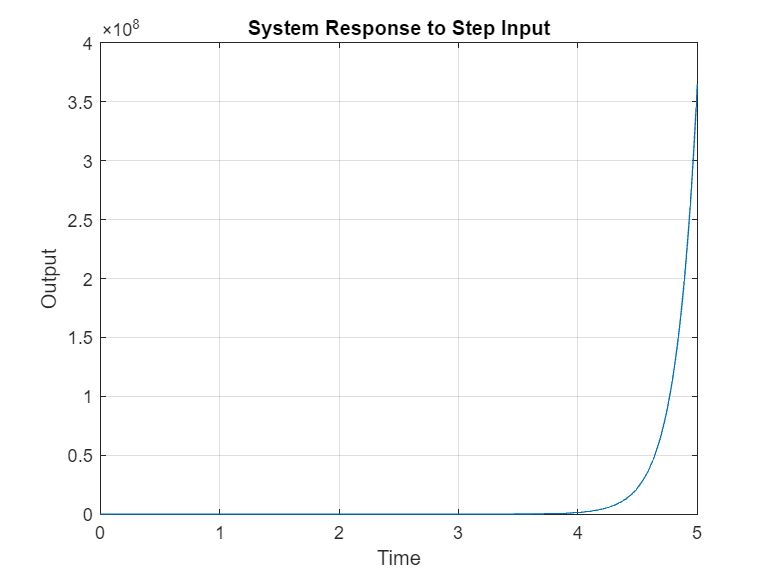

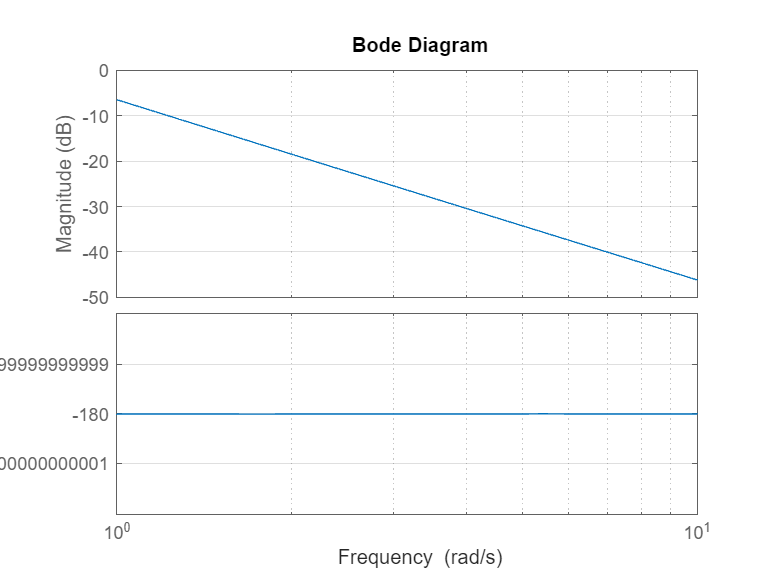


 Performing time-domain analysis using the step function

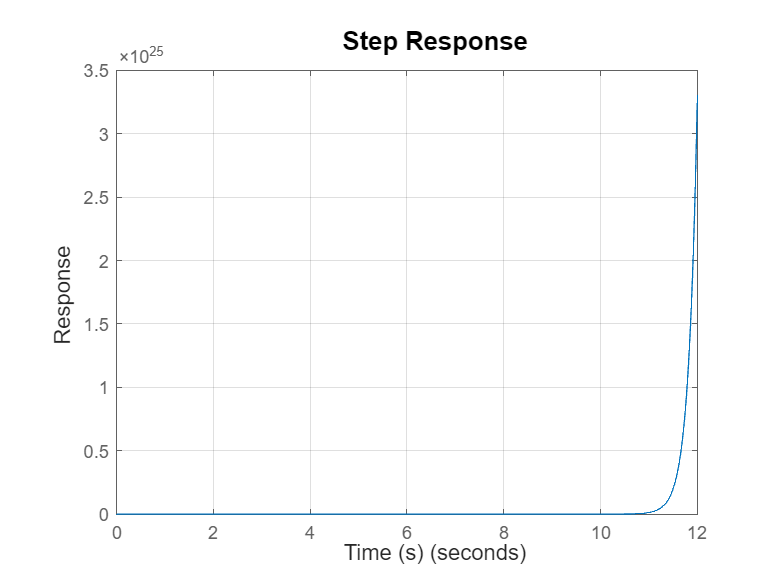


 Performing frequency-domain analysis using the pzmap function 


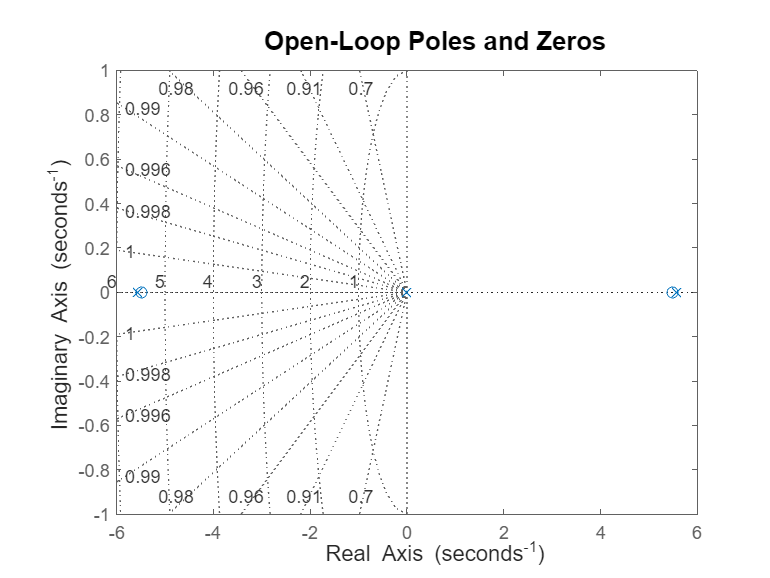

Using PLace we have K = 
 -188.1117  -34.5041   22.2784  -45.3747



% Etat du system
A = [0 1 0 0; 31.11 0 0 0; 0 0 0 1; -0.37 0 0 0];
B = [0 ;-1.48 ;0 ;0.4938];
C = [0 0 1 0];
D = 0;

% Polynome desire
p = [-5.8; -11.7; 0.42; -11.58];

% Calling the function i made to calculate everything
System_state(A,B,C,D,p);

a = 6;
b = 12;
c = -5.5776+6;
d = 5.5776+6;

poles2 = [-a; -b ;-c;-d];
K = place(A,B,poles2)

K =  -226.8492  -41.7116  -23.7677  -64.2631


#### nouveau modèle de représentation d'état pour le système bouclé

A2 = A-B*K;
B2 = [0 ;-1.48 ;0 ;0.4938];
C2 = [0 0 1 0];
D2 = 0;
sys2 = ss(A2,B2,C2,D2)

sys2 =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  -304.6  -61.73  -35.18  -95.11
   x3       0       0       0       1
   x4   111.6    20.6   11.74   31.73
 
  B = 
           u1
   x1       0
   x2   -1.48
   x3       0
   x4  0.4938
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


#### Avec Step

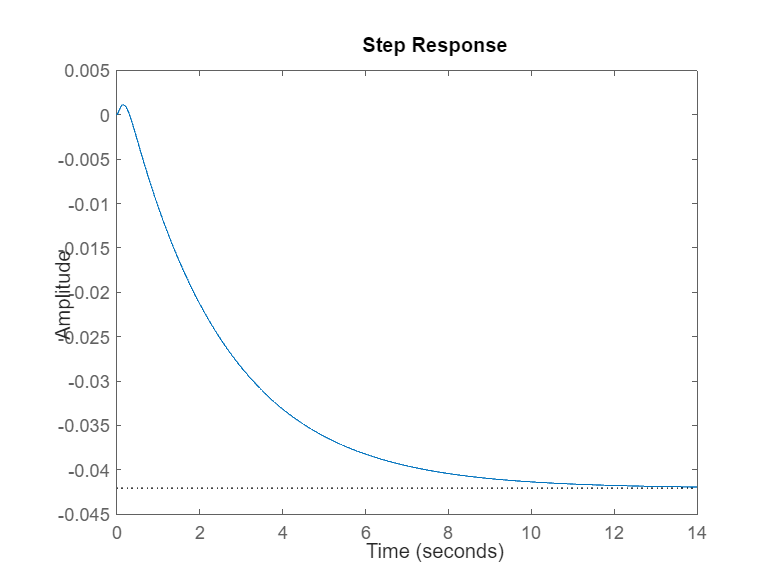

step(sys2);

### Avec lsim

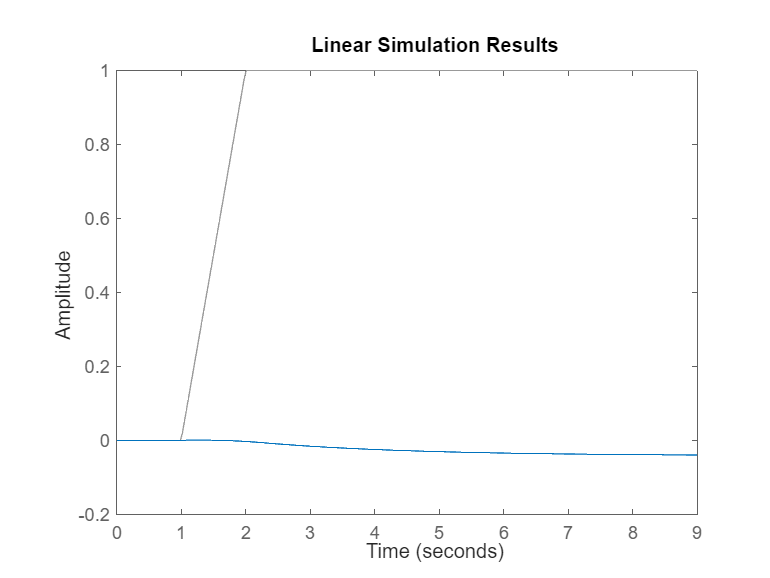

t = 0:0.03:9;  
u = max(0,min(t-1,1));
lsim(sys2,u,t);

#### `pzmap sytème en boucle ferme:`

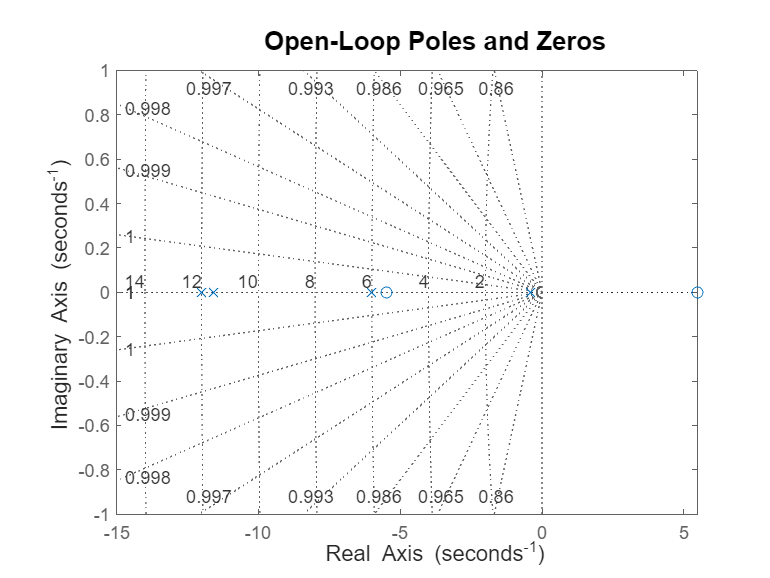

pzmap(sys2);
set(gcf, 'Color', 'w'); % Set the figure background color to white
title('Open-Loop Poles and Zeros', 'FontSize', 14, 'FontWeight', 'bold'); % Increase font size and make the title bold
xlabel('Real Axis', 'FontSize', 12); % Increase font size for x-axis label
ylabel('Imaginary Axis', 'FontSize', 12); % Increase font size for y-axis label
grid on; % Add grid lines to the plot